# From expt, get PDF of handover

A(t), x1(t), x1'(t), x2(t), x2'(t), f1(t), f2(t)

bag = ros2bagreader("rigid_gripper_expts_2/expt_8");

% read messages from 
% /area_sensor/float_array
% /object_linear_encoder/float_array

areaSensorBag = select(bag,"Topic", "/area_sensor/float_array");
objectEncoderBag = select(bag,"Topic", "/object_linear_encoder/float_array");
areaSensorMsgs = readMessages(areaSensorBag);
objectEncoderMsgs = readMessages(objectEncoderBag);

start_time = bag.StartTime;
end_time = bag.EndTime;

sample_freq = 50;
t = (start_time:0.02:end_time)';
t_biased = t-t(1);
n = size(t,1);

### Read and display area specifically

an = size(areaSensorMsgs,1);

area = zeros(8,an,"double"); %8xn vector containing area
at = zeros(an,1,"double"); %nx1 vector containing timestamps
% first 4 is right finger, second 4 is left

for i=1:an
    at(i) = areaSensorMsgs{i}.data(1);
    area(:,i) = areaSensorMsgs{i}.data(2:9);
end

at = at - start_time;

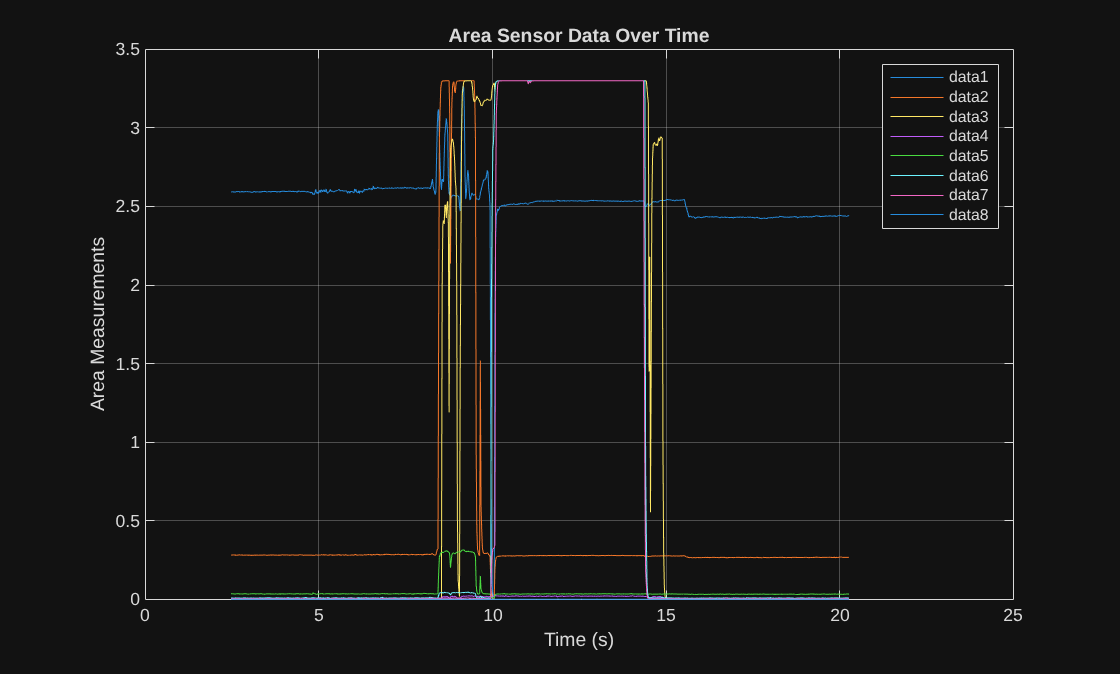

plot(at,area(:,:));
hold on;
legend;
xlabel('Time (s)');
ylabel('Area Measurements');
title('Area Sensor Data Over Time');
xlim([0 25]);
grid on;
hold off;

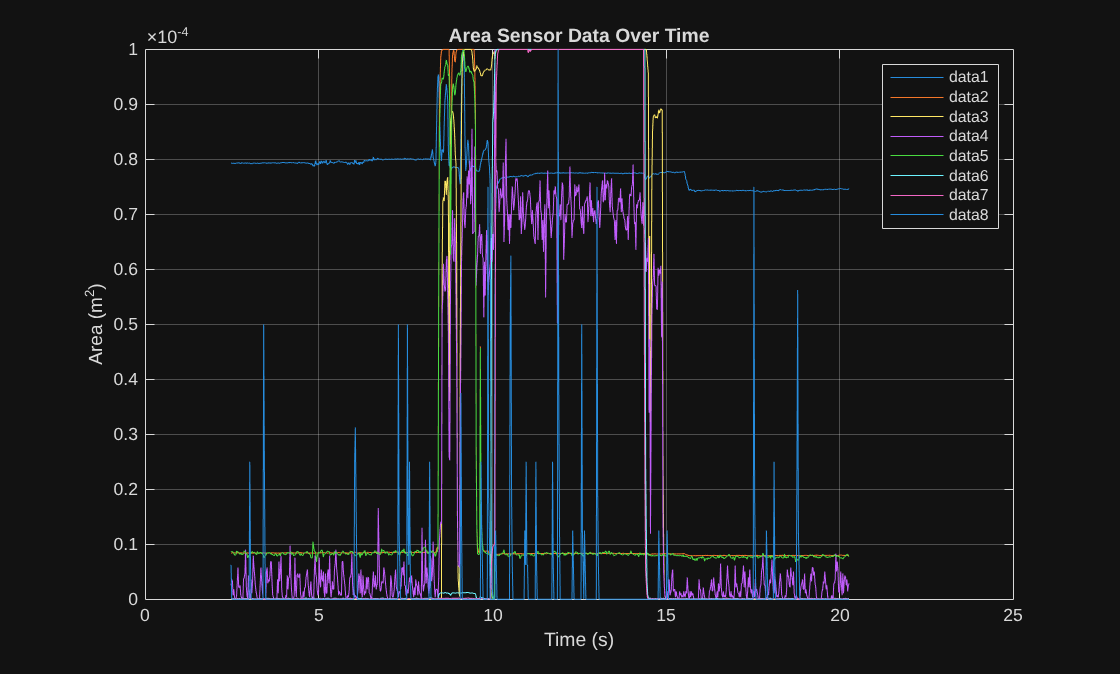

net_area = zeros(1,an);
for i=1:8
    area(i,:) = area(i,:) - min(area(i,:));
    area(i,:) = area(i,:)/max(area(i,:));
    area(i,:) = 1e-4*area(i,:);
    net_area = area(i,:) + net_area;
end

plot(at,area(:,:));
hold on;
legend;
xlabel('Time (s)');
ylabel('Area (m^2)');
title('Area Sensor Data Over Time');
xlim([0 25]);
grid on;
hold off;

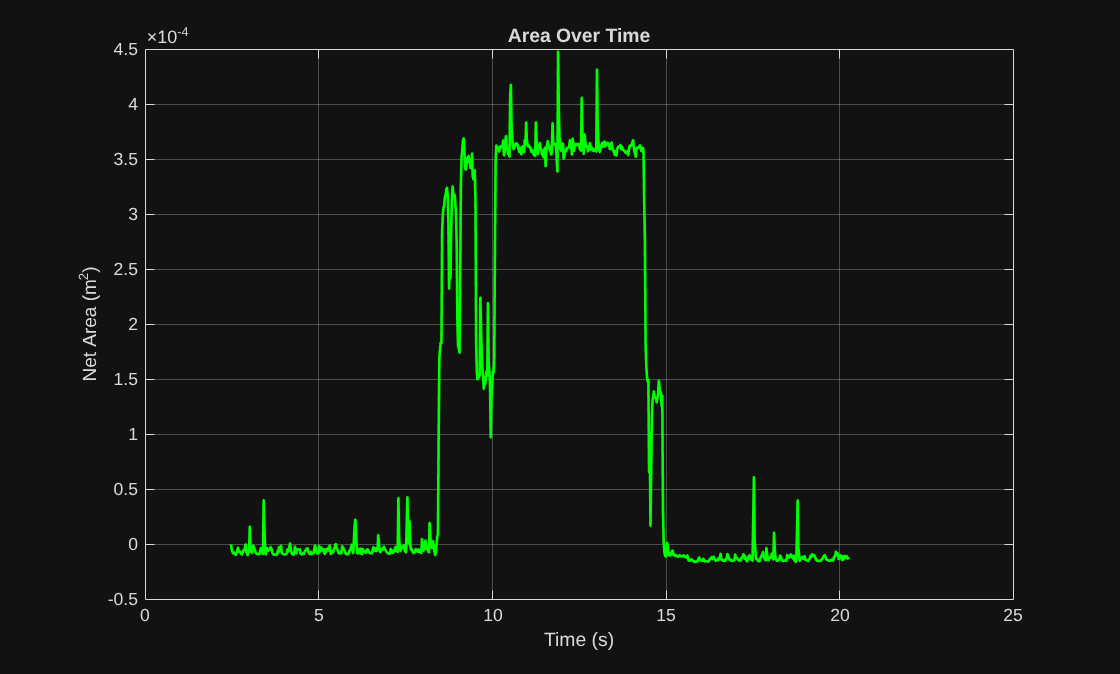


net_area = net_area - net_area(1);
plot(at,net_area',"LineWidth",1.5,"Color","green");
hold on;
xlabel('Time (s)');
ylabel('Net Area (m^2)');
title('Area Over Time');
xlim([0 25]);
grid on;
hold off;


net_area = net_area';

### Read and display object linear encoder data

on = size(objectEncoderMsgs,1);

% first is left second is right
objectEncoder = zeros(2,on); % 2xn array of object data
ot = zeros(on,1); % nx1 vector containing timestamps

for i=1:on
    ot(i) = objectEncoderMsgs{i}.data(1);
    objectEncoder(:,i) = objectEncoderMsgs{i}.data(2:3);
end

ot = ot -start_time;

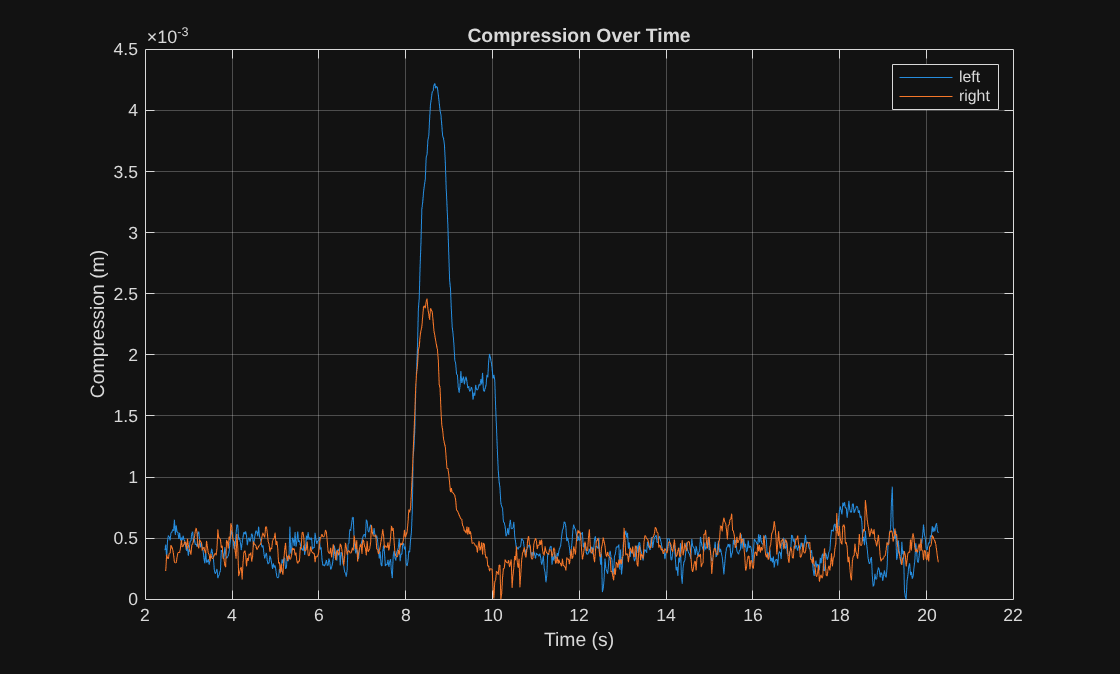

enc = (36*(objectEncoder'./3.3) - 30)./((objectEncoder'./3.3) -1);
enc(:,1) = enc(:,1) - min(enc(:,1));
enc(:,2) = enc(:,2) - min(enc(:,2));
enc = 1e-3*enc;
plot(ot,enc(:,1));
hold on;
plot(ot,enc(:,2));
xlabel("Time (s)");
ylabel("Compression (m)");
title("Compression Over Time");
legend(["left","right"]);
grid on;
hold off;

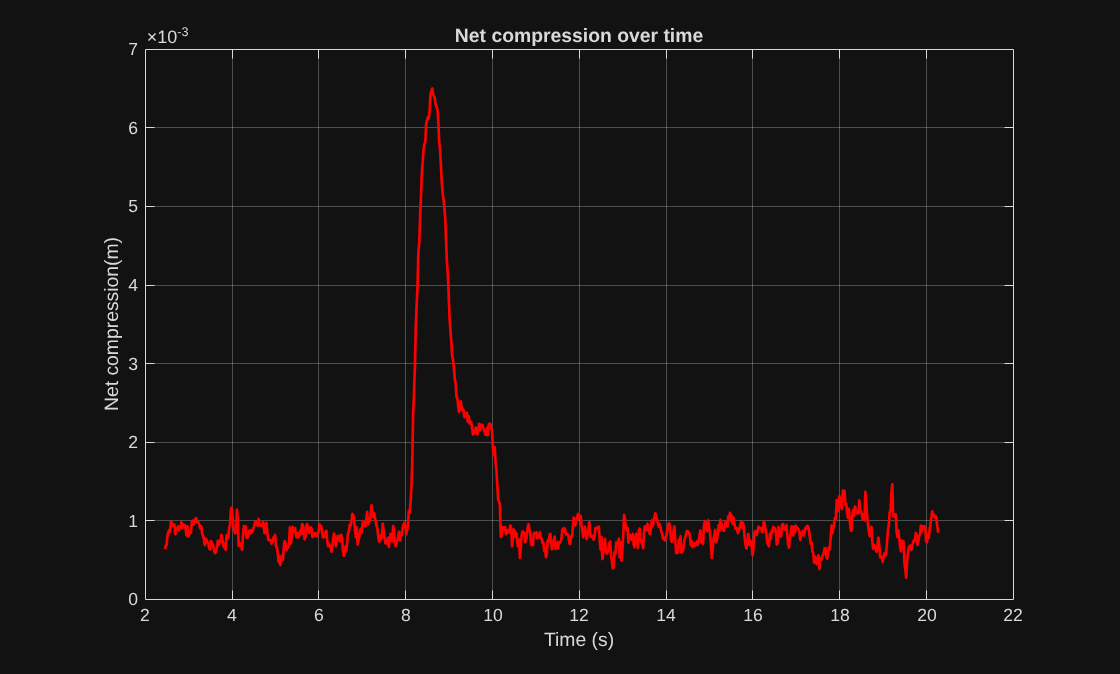


net_enc = enc(:,1) + enc(:,2);
plot(ot,net_enc,"LineWidth",1.5,"Color","red");
hold on;
title("Net compression over time");
ylabel("Net compression(m)");
xlabel("Time (s)");
grid on;
hold off;

Getting PFD for soft gripper expt 10

contact_start = 8.5;
contact_end = 11.5;

ot_start_idx = find(ot>=contact_start & ot<=contact_end,1);
ot_end_idx = find(ot>=contact_start & ot<=contact_end,1,"last");

at_start_idx = find(at>=contact_start & at<=contact_end,1);
at_end_idx = find(at>=contact_start & at<=contact_end,1,"last");

% net area of interest
% enc of interest enc(:,1) has left, enc(:,2) has right

contact_area = net_area(at_start_idx:at_end_idx);
contact_at = at(at_start_idx:at_end_idx) - at(at_start_idx);
contact_enc = enc(ot_start_idx:ot_end_idx,:);
contact_ot = ot(ot_start_idx:ot_end_idx) - ot(ot_start_idx);
contact_net_enc = contact_enc(:,1) + contact_enc(:,2);

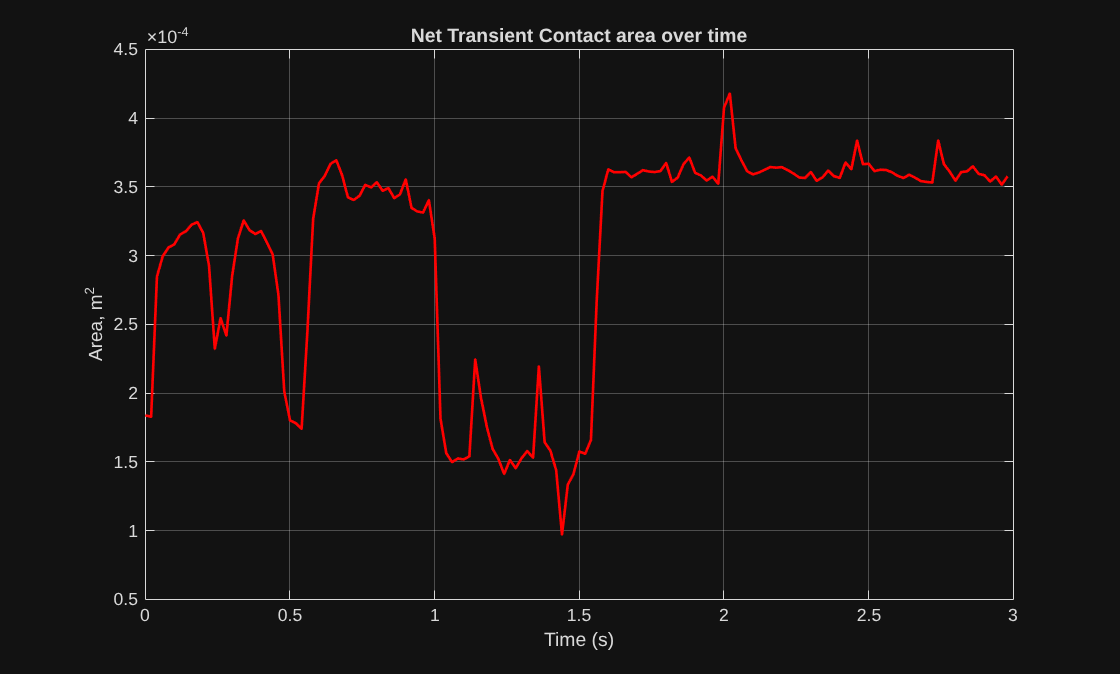

% plot contact area, contact enc  and then calc pfd
plot(contact_at,contact_area,"LineWidth",1.5,"Color","red");
hold on;
grid on;
title("Net Transient Contact area over time");
ylabel("Area, m^2");
xlabel("Time (s)");
hold off;

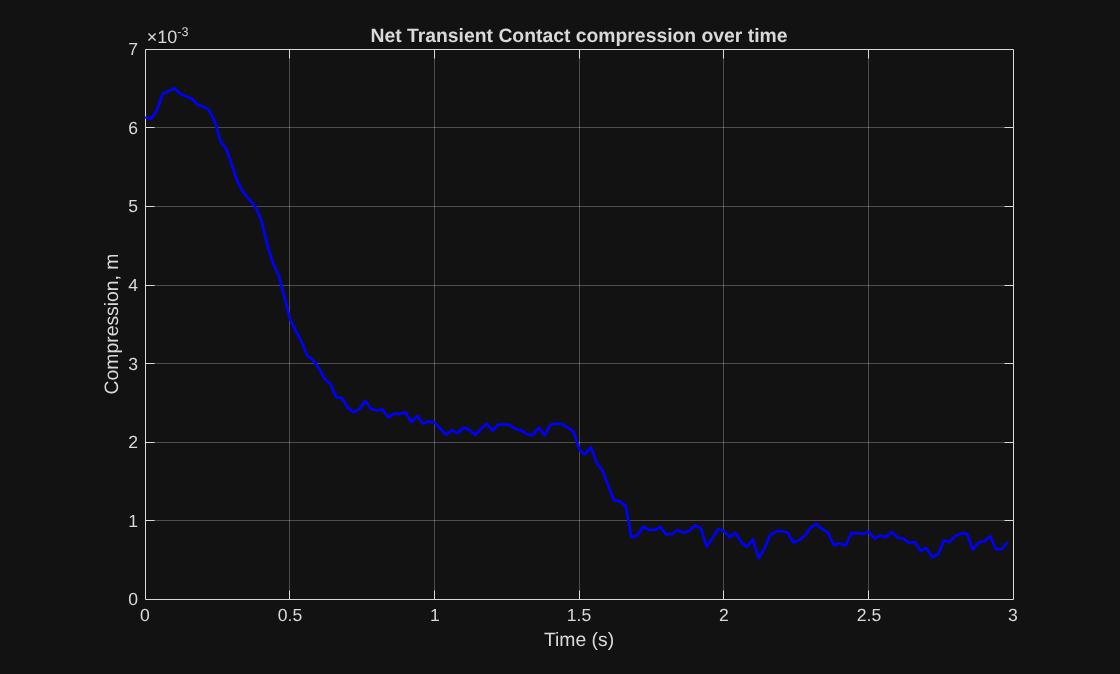


plot(contact_ot,contact_net_enc,"LineWidth",1.5,"Color","blue");
hold on;
grid on;
title("Net Transient Contact compression over time");
ylabel("Compression, m");
xlabel("Time (s)");
hold off;

Now get PFD

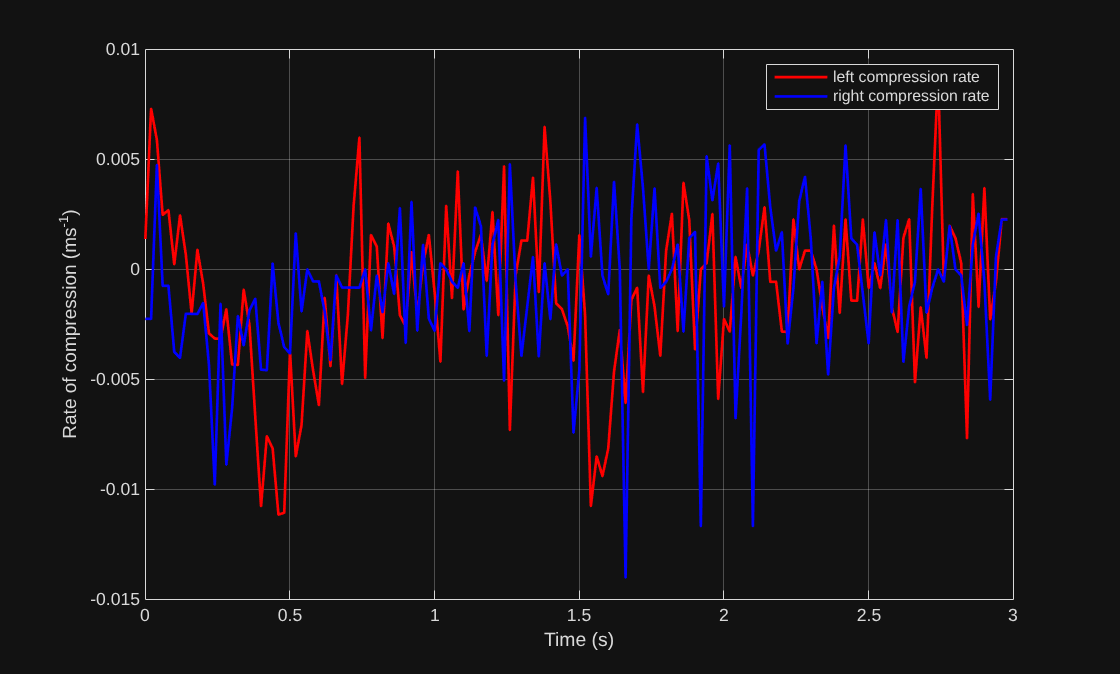

load("characteristic_2.mat");
l_comp = contact_enc(:,1);
r_comp = contact_enc(:,2);

vl_comp = diff(l_comp)/0.02;
vr_comp = diff(r_comp)/0.02;
vl_comp(end+1)=vl_comp(end);
vr_comp(end+1)=vr_comp(end);

% plot velocity of compression over time
plot(contact_ot,vl_comp,"LineWidth",1.5,"Color","red");
hold on;
plot(contact_ot,vr_comp,"LineWidth",1.5,"Color","blue");
legend(["left compression rate","right compression rate"]);
grid on;
xlabel("Time (s)");
ylabel("Rate of compression (ms^{-1})");
hold off

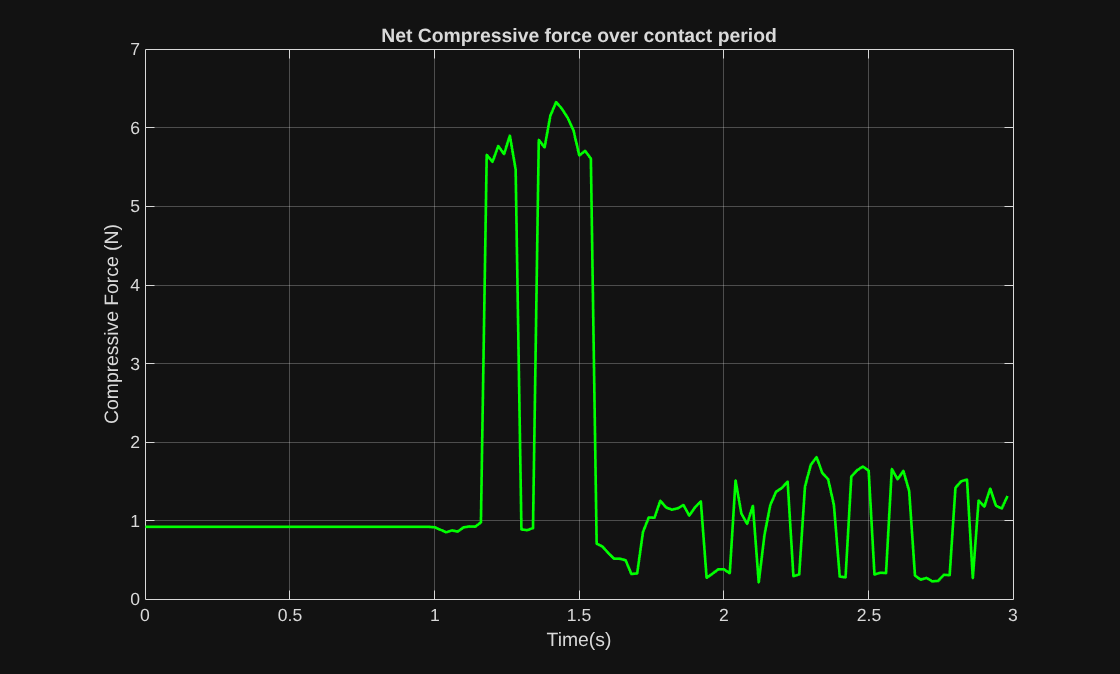


fl_comp = -1*estimate_lattice_force(l_comp,contact_ot,t_inv,k,r(1),r(2),kr);
fr_comp = -1*estimate_lattice_force(r_comp,contact_ot,t_inv,k,r(1),r(2),kr);

plot(contact_ot,fl_comp+fr_comp,"LineWidth",1.5,"Color","green");
hold on;
title("Net Compressive force over contact period");
xlabel("Time(s)");
ylabel("Compressive Force (N)");
grid on;
hold off;

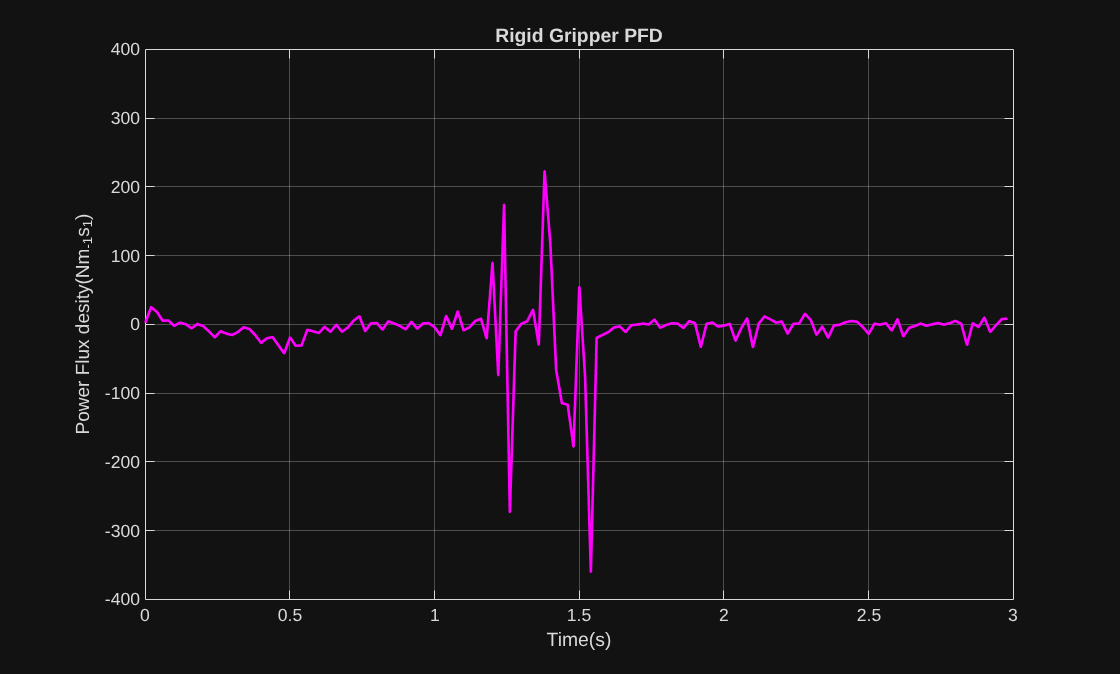

rigid_pfd = (fr_comp.*vr_comp + fl_comp.*vl_comp)./contact_area;
plot(contact_ot,rigid_pfd,"LineWidth",1.5,"Color","magenta");
hold on;
title("Rigid Gripper PFD");
xlabel("Time(s)");
ylim([-400,400]);
grid on;
ylabel("Power Flux desity(Nm_{-1}s_{1})");